# پاسخ های زمانی

## صفرها و قطب ها

### قطب

برای نمایش دادن صفرها و قطبها در سیستم، از دستور زیر استفاده کنید. آرگومان ورودی میتواند از هر نوع سیستم باشد یعنی فضای حالت، تابع تبدیل یا نمایش صفر-قطب-بهره

[`P = pole(sys)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.pole.html?snc=ABB4XK&searchsource=mw%203p&container=jshelpbrowser#d124e131334)

این دستور برداری ستونی که حاوی قطبهای سیستم است، را بر میگرداند

#### مثال


$$G=\frac{1}{s^3 +2s^2 +3s+5}$$


sys = tf(1, [1 2 3 5]);
poles = pole(sys)

poles =   -1.8437 + 0.0000i
  -0.0781 + 1.6449i
  -0.0781 - 1.6449i


این دستور هر سه کلاس سیستمهای خطی تغییرناپذیر با زمان را می پذیرد

### صفر

دستور زیر از هر نمایش سیستمی استفاده میکند و خروجی آن صفرهای انتقال سیستم است

[`Z = zero(sys)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.zero.html?snc=VKJOMD&searchsource=mw%203p&container=jshelpbrowser#d124e188566)

[`[Z,gain] = zero(sys)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.zero.html?snc=VKJOMD&searchsource=mw%203p&container=jshelpbrowser#d124e188585)

gain: ضریب "اس" با بزرگترین توان در صورت

#### مثال


$$G=\frac{4\ldotp 5s^2 +2s+1}{s^3 +2s^2 +3s+5}$$


sys = tf([4.5 2 1], [1 2 3 5]);
zeros = zero(sys)

zeros =   -0.2222 + 0.4157i
  -0.2222 - 0.4157i


[zeros, gain] = zero(sys)

zeros =   -0.2222 + 0.4157i
  -0.2222 - 0.4157i


gain = 4.5000

### بهره دی سی

بهره فرکانس های پایین یا بهره دی سی با دستور زیر بدست می آید. این دستور مشابه این است که در تابع تبدیل بجای "اس" صفر گذاشته باشید و یا مقدار نهایی تابع تبدیل پس از اعمال ورودی پله را بدست آورده باشید

`k = dcgain(sys)`

#### مثال


$$G=\frac{4\ldotp 5s^2 +2s+1}{s^3 +2s^2 +3s+5}$$


sys = tf([4.5 2 1], [1 2 3 5]);
gain_dc = dcgain(sys)

gain_dc = 0.2000

### نقشه صفر و قطب

با وارد کردن دستور زیر یک پنجره باز خواهد شد که در آن صفرها با علامت دایره و قطب ها با علامت ضربدر مشخص شده اند. آرگومان میتواند از هر نوع نمایش سیستم باشد

[`pzmap(sys)`](https://127.0.0.1:31515/static/help/control/ref/lti.pzmap.html#d124e133833)

این دستور همچنین مقادیر صفر و قطب را نیز برمیگرداند

[`[p,z] = pzmap(sys)`](https://127.0.0.1:31515/static/help/control/ref/lti.pzmap.html#d124e133899)

p: قطب ها

z: صفرها

#### مثال


$$G=\frac{4\ldotp 5s^2 +2s+1}{s^3 +2s^2 +3s+5}$$


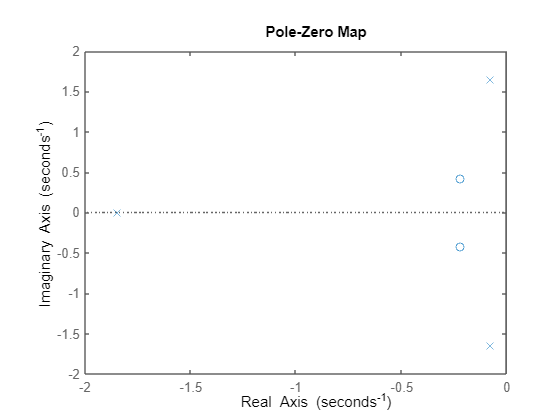

sys = tf([4.5 2 1], [1 2 3 5]);
figure
pzmap(sys)

[poles, zeros] = pzmap(sys)

poles =   -1.8437 + 0.0000i
  -0.0781 + 1.6449i
  -0.0781 - 1.6449i


zeros =   -0.2222 + 0.4157i
  -0.2222 - 0.4157i


رسم دو تابع

$G_1 =\frac{4\ldotp 5s^2 +2s+1}{s^3 +2s^2 +3s+5}$, $G_2 =\frac{s^2 +3s+2}{s^3 +5s^2 +s+2}$

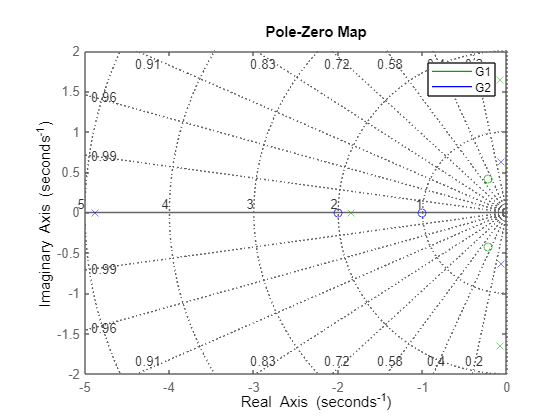

sys1 = tf([4.5 2 1], [1 2 3 5]);
sys2 = tf([1 3 2], [1 5 1 2]);
figure
pzmap(sys1, 'g', sys2, 'b')
legend('G1', 'G2'); grid on

در این مثال رنگ نقشه هر سیستم به رنگ دلخواه ما در امد. در صورت عدم استفاده از کارکترهای کنترل رنگ و شکل منحنی، این کار به صورت پیش فرض انجام خواهد شد

## پاسخ های زمانی

### رسم پاسخ پله

برای رسم پاسخ پله از دستور زیر استفاده کنید. تفاوتی نخواهد داشت اگر از شی تابع تبدیل یا هر شی دیگری استفاده کنید

[`step(sys)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.step.html#d124e162707)

sys: یکی از سه مدل سیستم (تابع تبدیل، فضای حالت یا صفر-قطب-بهره)

[`step(sys1,sys2,...,sysN,``___``)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.step.html#d124e162792)

sys1, sys2, ..., sysN: چندین مدل سیستم برای رسم چندین پاسخ در یک پنجره جهت مقایسه پاسخ ها یا موارد دیگر

برای تعیین زمان نهایی رسم یعنی شبیه سازی تا به زمانی مشخص، از دستور زیر استفاده کنید

[`step(sys,tFinal)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.step.html#d124e162730)

tFinal: یک عدد اسکالر که آخرین لحظه شبیه سازی یا همان مدت زمان را نشان می دهد. یعنی شبیه سازی تنها تا زمان مشخص شده انجام شود

این دستور همچنین میتواند تنها در نقاطی که توسط کاربر مشخص شده اند، شبیه سازی کند

[`step(sys,t)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.step.html#d124e162870)

t: یک بردار که نقاط زمانی شبیه سازی را مشخص میکند. یعنی نمونه های زمانی شبیه سازی باید عضوی از این بردار باشند

برای بازگرداندن منحنی پاسخ پله از سینتکس زیر استفاده کنید

[`y = step(sys,t)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.step.html#d124e162892)

t: شامل منحنی پاسخ پله است که شبیه سازی آن بر روی بردار زمان "تی" انجام شده است. از این خروجی میتوانید برای پردازش سیگنال خروجی سیستم یا هر موارد دیگر استفاده کنید

[`[y,tOut] = step(sys)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.step.html#d124e162909)

tOut: اگر بردار زمانی خاصی را مشخص نکرده باشید، شبیه سازی برای یک بردار مناسب زمانی انجام خواهد شد و این بردار برای شما در این متنغیر ذخیره خواهد شد

y: منحنی پاسخ پله نیز در این متغیر ذخیره خواهد شد. هر درایه از این ماتریس متناظر با همان درایه در متغیر بردار زمان است، یعنی میتوانید آن ها را بر حسب هم رسم کنید

[`[y,tOut] = step(sys,tFinal)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.step.html#d124e162933)

tOut: در این سینتکس بردار زمانی مشخص نشده بلکه تنها نقطه پایانی شبیه سازی یا همان مدت زمان مشخص شده است. بنابراین بردار زمانی در این متغیر ذخیره میشود که آخرین درایه آن توسط خود شما مشخص شده است

y: منحنی پاسخ پله نیز در این متغیر ذخیره میشود

اما دستور زیر تنها نمایش فضای حالت را می پذیرد و علاوه بر خروجی، حالت های سیستم را نیز بر میگرداند

[`[y,t,x] = step(sys)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.step.html?snc=MC3VVD&searchsource=mw%203p&container=jshelpbrowser#d124e162956)

y: خروجی در حضور وردی پله

t: بردار زمانی که شبیه سازی بر روی آن انجام شده

x: حالت های سیستم. یک ماتریس است که تعداد ستون های آن با تعداد حالت های سیستم برابر است، یعنی هر ستون آن شمال منحنی یک حالت است

که سینتکس اول شبیه سازی را برای برداز زمان شما و سینتکس دوم برای مقادیر پیش فرض زمان انجام میدهد

#### مثال

$G_1 =\frac{4\ldotp 5s^2 +2s+1}{s^3 +2s^2 +3s+5}$, $G_2 =\frac{s^2 +3s+2}{s^3 +5s^2 +s+2}$


$$A=\left\lbrack \begin{array}{cc}
-1\ldotp 5 & -2\\
1 & 0
\end{array}\right\rbrack ,B=\left\lbrack \begin{array}{c}
0\ldotp 5\\
0
\end{array}\right\rbrack ,C=\left\lbrack \begin{array}{cc}
0 & 1
\end{array}\right\rbrack ,D=0$$


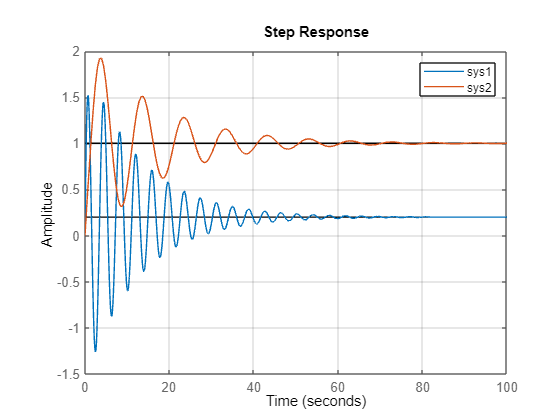

sys1 = tf([4.5 2 1], [1 2 3 5]);
sys2 = tf([1 3 2], [1 5 1 2]);
step(sys1, sys2)
legend('sys1', 'sys2')
grid on

رسم در مدت زمان مشخص شده

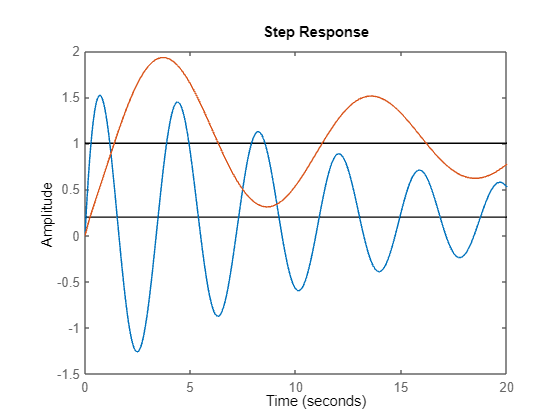

step(sys1, sys2, 20)

رسم با بردار زمانی مشخص شده

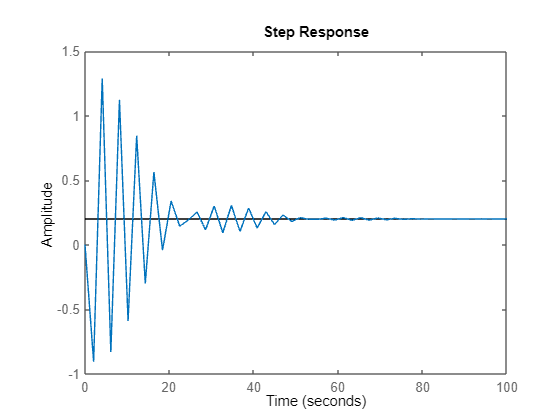

t = linspace(0, 100, 50);
step(sys1, t)

برگرداندن منحنی پاسخ پله

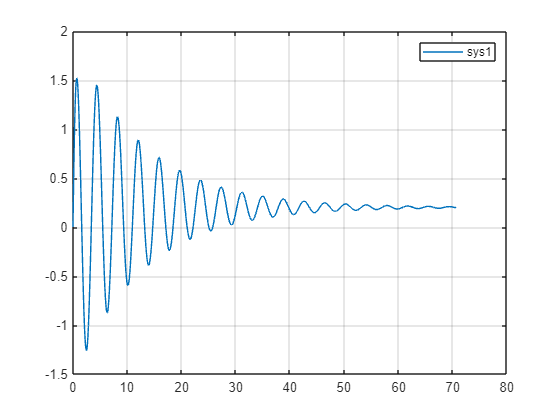

[y, tout] = step(sys1);
plot(tout, y)
legend('sys1')
grid on

برگرداندن پاسخ پله با زمان مشخص شده

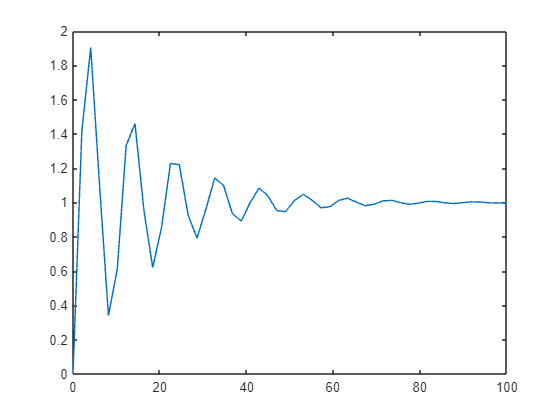

y = step(sys2, t);
plot(t, y)

مقادیر حالت سیستم فضای حالت را نیز رسم کنید

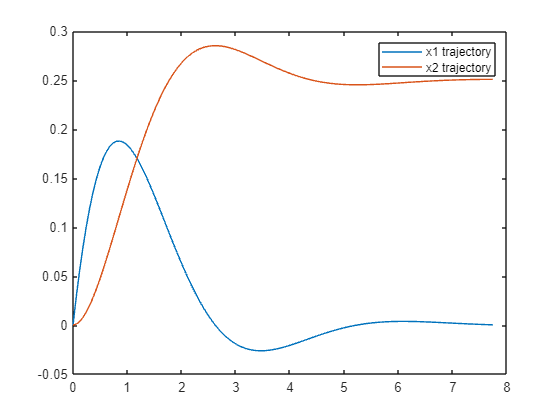

A = [-1.5, -2;...
    1, 0];
B = [0.5;...
    0];
C = [0, 1];
D = 0;
sys = ss(A, B, C, D);
[y,t,x] = step(sys);
figure
plot(t, x)
legend('x1 trajectory', 'x2 trajectory')

### اطلاعات پاسخ پله

اگر به اطلاعات نظیر فراجهش یا زمان نشست نیاز دارید، با دستور زیر آن را مستقیما بدست آورید و نیاز به دستور قبلی برای یافتن منحنی پاسخ و پردازش آن نیست

[`S = stepinfo(sys)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.stepinfo.html?snc=GEKW0W&searchsource=mw%203p&container=jshelpbrowser#d124e165159)

این دستور یک ساختار برمیگرداند که در آن هر ویژگی پاسخ پله به همراه مقدار آن نمایش داده میشود. آرگومان ورودی هر نمایشی از سیستم میتواند باشد

ویژگی هایی که نمایش داده خواهند شد به شرح زیر است

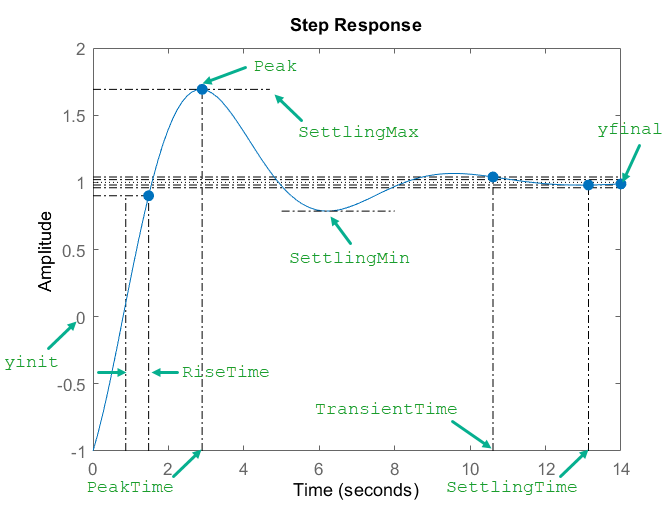

### مثال


$$G=\frac{1}{s^2 +10s+1}$$


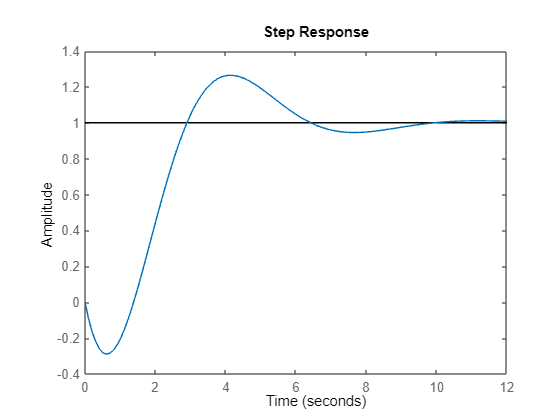

G = tf([-1 1], [1 0.9 1]);
figure
step(G)

S = stepinfo(G)

S = struct with fields:
         RiseTime: 1.1708
    TransientTime: 8.9631
     SettlingTime: 9.1517
      SettlingMin: 0.9330
      SettlingMax: 1.2645
        Overshoot: 26.4535
       Undershoot: 28.9410
             Peak: 1.2645
         PeakTime: 4.0935

برای دسترسی به هر مقدار آن کافیست از سینتکس زیر استفاده کنید. سینتکس زیر به عنوان مثال فروجهش سیستم را بر میگرداند

under = S.Undershoot

under = 28.9410

و یا مثال زیر قله پاسخ پله را نمایش میدهد

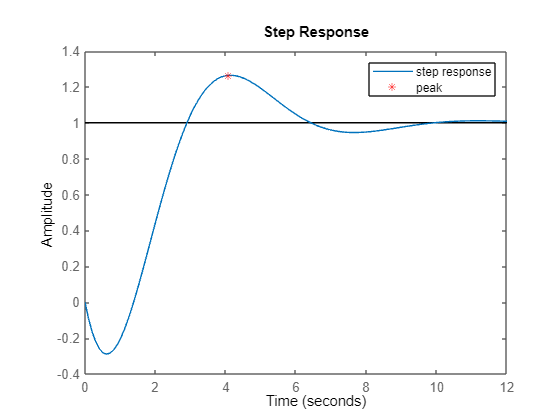

t_peak = S.PeakTime;
peak = S.Peak;
figure
step(G)
hold on
scatter(t_peak, peak, 'r*')
legend('step response', 'peak')

### پاسخ ضربه

برای رسم پاسخ ضربه از دستورات زیر استفاده کنید

[`impulse(sys)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.impulse.html?snc=JMJZSI&searchsource=mw%203p&container=jshelpbrowser#d124e73463)

[`impulse(sys,tFinal)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.impulse.html?snc=JMJZSI&searchsource=mw%203p&container=jshelpbrowser#d124e73517)

[`impulse(sys,t)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.impulse.html?snc=JMJZSI&searchsource=mw%203p&container=jshelpbrowser#d124e73538)

[`impulse(sys1,sys2,...,sysN,``___``)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.impulse.html?snc=JMJZSI&searchsource=mw%203p&container=jshelpbrowser#d124e73579)

[`y = impulse(sys,t)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.impulse.html?snc=JMJZSI&searchsource=mw%203p&container=jshelpbrowser#d124e73657)

[`[y,tOut] = impulse(sys)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.impulse.html?snc=JMJZSI&searchsource=mw%203p&container=jshelpbrowser#d124e73696)

[`[y,tOut] = impulse(sys,tFinal)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.impulse.html?snc=JMJZSI&searchsource=mw%203p&container=jshelpbrowser#d124e73720)

نحوه بکار بردن این دستور نیز شبیه دستور پاسخ پله است که بحث شد. در نتیجه انتظار میرود بدانید که هر کدام از دستورات بالا چه کاربردی دارند

#### مثال


$$G_1 =\frac{4\ldotp 5s^2 +2s+1}{s^3 +2s^2 +3s+5}$$


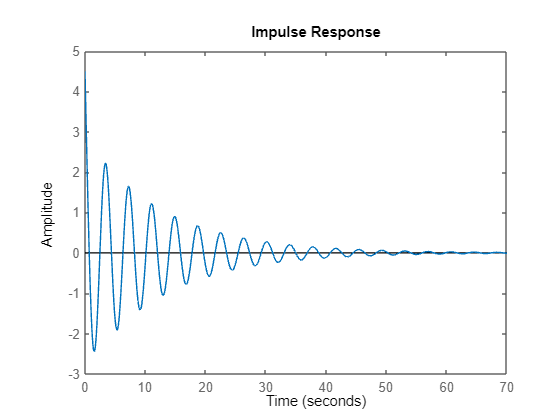

sys1 = tf([4.5 2 1], [1 2 3 5]);
figure
impulse(sys1)

### پاسخ به شرایط اولیه غیر صفر

این دستور تنها برای مدل فضای حالت کار خواهد کرد. در صورت تبدیل مدل تابع تبدیل به فضای حالت این دستور معتبر نخواهد بود زیرا در هنگام یافتن تابع تبدیلی برای سیستم، از شرایط اولیه صرف نظر شده است. سینتکس این دستور به شرح زیر است

[`initial(sys,x0)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.initial.html?snc=H0HXK1&searchsource=mw%203p&container=jshelpbrowser#d124e76567)

x0: برداری برای شرایط اولیه سیستم که تعداد عناصر آن برابر با تعداد حالت های سیستم است

با دستور زیر مدت زمان شبیه سازی را مشخص کنید

[`initial(sys,x0,tFinal)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.initial.html?snc=H0HXK1&searchsource=mw%203p&container=jshelpbrowser#d124e76598)

با دستور زیر شبیه سازی را برای بردار زمانی خود انجام دهید

[`initial(sys,x0,t)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.initial.html?snc=H0HXK1&searchsource=mw%203p&container=jshelpbrowser#d124e76621)

منحنی پاسخ پله را در متغیری ذخیره کنید. شبیه سازی آن بر روی بردار زمان خود شما انجام شده است

[`y = initial(sys,x0,t)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.initial.html?snc=H0HXK1&searchsource=mw%203p&container=jshelpbrowser#d124e76750)

با شرایط اولیه یکسان برای چندین سیستم مجزا شبیه سازی کنید

[`initial(sys1,sys2,...,sysN,x0,``___``)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.initial.html?snc=H0HXK1&searchsource=mw%203p&container=jshelpbrowser#d124e76692)

شبیه سازی را برای بردار زمانی پیش فرض متلب انجام دهید و منحنی پاسخ، بردار زمانی و حالت های سیستم را نیز ذخیره کنید

[`[y,tOut,x] = initial(sys,x0)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.initial.html?snc=H0HXK1&searchsource=mw%203p&container=jshelpbrowser#d124e76816)

با مطالعه نحوه استفاده از دستور پاسخ پله و مثال های داخل همین فایل، بایستی این دستورات را هم به راحتی متوجه شوید

#### مثال


$$A=\left\lbrack \begin{array}{cc}
-1\ldotp 5 & -2\\
1 & 0
\end{array}\right\rbrack ,B=\left\lbrack \begin{array}{c}
0\ldotp 5\\
0
\end{array}\right\rbrack ,C=\left\lbrack \begin{array}{cc}
0 & 1
\end{array}\right\rbrack ,D=0$$


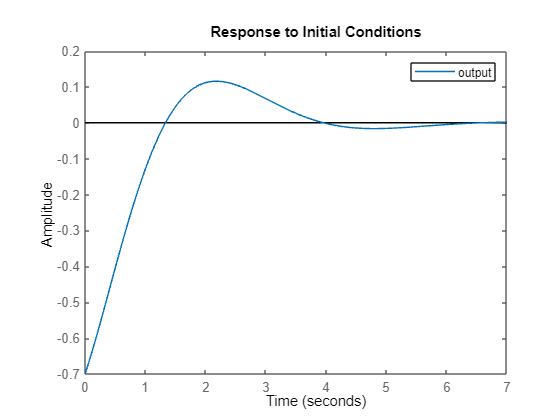

A = [-1.5, -2;...
    1, 0];
B = [0.5;...
    0];
C = [0, 1];
D = 0;
sys = ss(A, B, C, D);
figure
initial(sys, [0.5, -0.7])
legend('output')

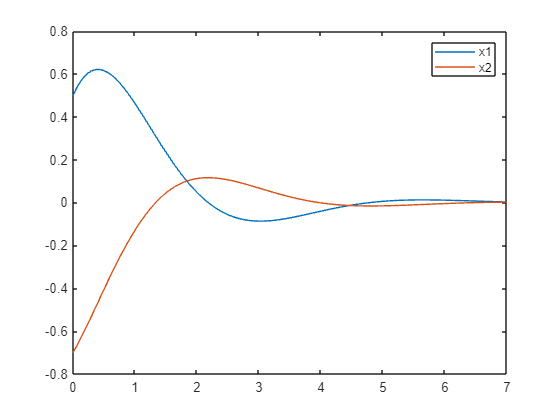

[y,tOut,x] = initial(sys,[0.5, -0.7]);
figure
plot(tOut, x)
legend('x1', 'x2')

### دستور تولید سیگنال

برای رسم پاسخ سیستم به ورودی دلخواه، نیاز به سیگنال ورودی دارید. روش های فراوانی برای این کار وجود دارد اما بررسی سینتکس زیر خالی از لطف نیست. این سینتکس توانایی تولید سیگنال سینوسی، مربعی و پالس را دارا است

[`[u,t] = gensig(type,tau)`](https://127.0.0.1:31515/static/help/control/ref/gensig.html?snc=3XX7JZ&searchsource=mw%203p&container=jshelpbrowser#d124e55358)

[`[u,t] = gensig(type,tau,Tf)`](https://127.0.0.1:31515/static/help/control/ref/gensig.html?snc=3XX7JZ&searchsource=mw%203p&container=jshelpbrowser#d124e55401)

[`[u,t] = gensig(type,tau,Tf,Ts)`](https://127.0.0.1:31515/static/help/control/ref/gensig.html?snc=3XX7JZ&searchsource=mw%203p&container=jshelpbrowser#d124e55431)

u: سیگنال مطلوب که توسط این دستور و تنظیمات شما تولید شده است

t: بردار زمانی متناظر با سیگنال تولید شده

type: یک رشته که نوع سیگنال مطلوب را مشخص میکند

        'sine': سینوسی

        'square': مربعی

        'pulse': پالس

tau: دوره تناوب سیگنال تولیدی

Tf: مدت زمان تولید سیگنال

Ts: قدم زمانی شبیه سازی یا همان فاصله بین هر دو درایه از بردار زمان

به جز نوع سیگنال، سه آرگومان ورودی داریم که از بین آن ها دوره تناوب باید مشخص شود و دیگر آرگومان ها نیز مقدار پیش فرض دارند. مقدار پیش فرض مدت زمان برابر با 5 دوره تناوب و قدم زمانی برابر با 1/64 دوره تناوب است. بردار زمانی شبیه سازی به صورت زیر خواهد بود:

t = 0:Ts:Tf;

اگر با این سینتکس آشنایی ندارید، دو متغیر را با عدد جایگذاری کنید و در محیط دستور اجرا نمایید

#### مثال

تولید موج مربعی با دوره تناوب 2 ثانیه

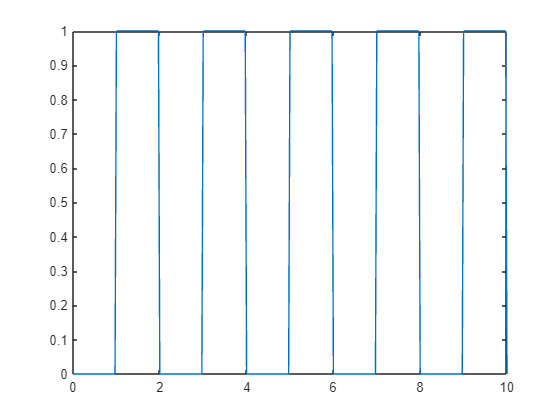

tau = 2;
[u,t] = gensig("square",tau);
figure
plot(t,u)

موج سینوسی با دوره تناوب 3، با دو دوره تناوب یا مدت زمان 6 ثانیه و قدم زمانی 0.1 ثانیه

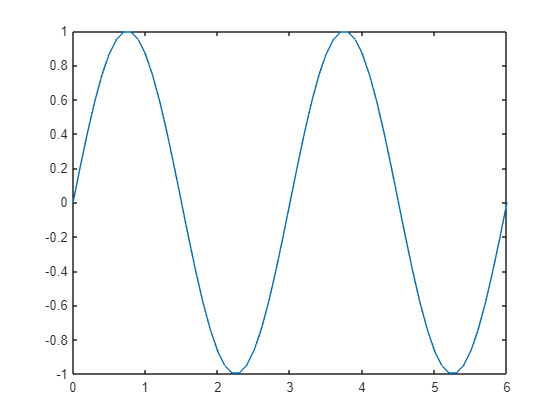

tau = 3;
Tf = 6;
Ts = 0.1;
[u,t] = gensig("sine",tau,Tf,Ts);
figure
plot(t,u)

تولید پالس با دوره تناوب 3، 4 دروه تناوب و قدم زمانی 0.1

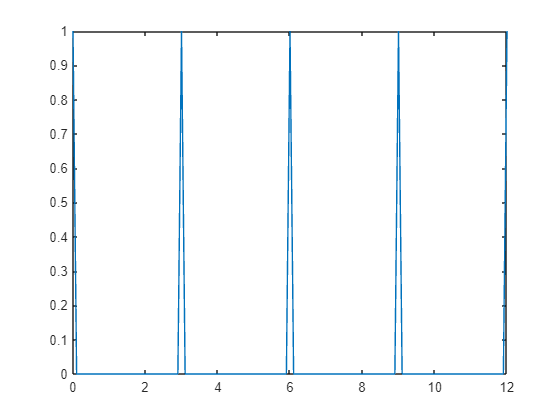

tau = 3;
Tf = 12;
Ts = 0.1;
[u,t] = gensig("pulse",tau,Tf,Ts);
figure
plot(t,u)

### پاسخ سیستم به ورودی دلخواه

این دستورات هر نوع نمایشی از سیستم را می پذیرد و با توجه به بردار زمانی ورودی و منحنی ورودی، پاسخ سیستم را محاسبه خواهد کرد

[`lsim(sys,u,t)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.lsim.html?snc=L2UVRJ&searchsource=mw%203p&container=jshelpbrowser#d124e89571)

u: منحنی سیگنال ورودی

t: بردار زمانی متناظر با آن ورودی

دستور زیر تنها مدلی فضای حالت را می پذیرد و علاوه بر ورودی، حالته های اولیه سیستم را در پاسخ دخالت خواهد داد

[`lsim(sys,u,t,x0)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.lsim.html?snc=L2UVRJ&searchsource=mw%203p&container=jshelpbrowser#d124e89613)

x0: بردار شرایط اولیه که تعداد عناصر آن با تعداد حالت های سیستم برابر است

[`lsim(sys,u,t,x0,method)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.lsim.html?snc=L2UVRJ&searchsource=mw%203p&container=jshelpbrowser#d124e89663)

method: یک رشته که نوع گسسته سازی را مشخص میکند. شبیه سازی این دستور با گسسته سازی سیستم پیوسته با فرکانسی که بردار زمان شما مشخص میکند، انجام میشود

        'zoh': روش گسسته سازی نگهدار مرتبه صفر

        'foh': روش نگهدار مرتبه اول

        اگر مشخص نشود، به صورت پیش فرض با توجه به نرمی سیگنال مشخص میشود

پاسخ چندین سیستم را با ورودی یکسان رسم خواهد کرد. در این صورت میتوانید با ورودی یکسان، پاسخ سیستم های مختلف را مقایسه کنید

[`lsim(sys1,sys2,...,sysN,u,t,``___``)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.lsim.html?snc=L2UVRJ&searchsource=mw%203p&container=jshelpbrowser#d124e89686)

با دستور زیر میتوانید خروجی را ذخیره کنید

[`y = lsim(sys,u,t)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.lsim.html?snc=L2UVRJ&searchsource=mw%203p&container=jshelpbrowser#d124e89746)

دستور زیر تنها نمایش فضای حالت را می پذیرد و شبیه سازی را به همراه پاسخ به شرایط اولیه مشخص انجام میدهد

[`y = lsim(sys,u,t,x0)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.lsim.html?snc=L2UVRJ&searchsource=mw%203p&container=jshelpbrowser#d124e89781)

روش شبیه سازی را برای سینتکس بالا مشخص کنید

[`y = lsim(sys,u,t,x0,method)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.lsim.html?snc=L2UVRJ&searchsource=mw%203p&container=jshelpbrowser#d124e89828)

دستور زیر که تنها نمایش فضای حالت را می پذیرد، حالت های سیستم را نیز بر خواهد گرداند

[`[y,tOut,x] = lsim(``___``)`](https://127.0.0.1:31515/static/help/control/ref/dynamicsystem.lsim.html?snc=L2UVRJ&searchsource=mw%203p&container=jshelpbrowser#d124e89852)

#### مثال

پاسخ خروجی و حالت های سیستم زیر را به ورودی شیب بررسی کنید


$$A=\left\lbrack \begin{array}{cc}
-1\ldotp 5 & -2\\
1 & 0
\end{array}\right\rbrack ,B=\left\lbrack \begin{array}{c}
0\ldotp 5\\
0
\end{array}\right\rbrack ,C=\left\lbrack \begin{array}{cc}
0 & 1
\end{array}\right\rbrack ,D=0$$


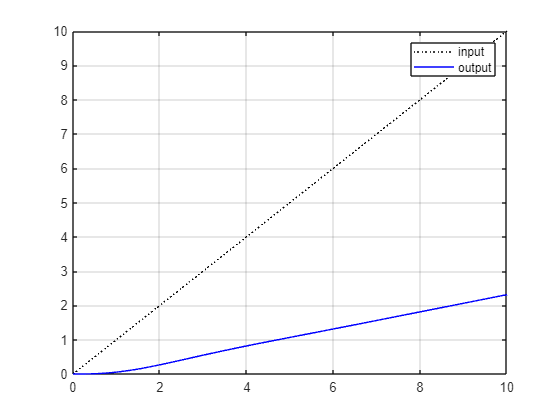

t = 0:0.1:10;
u = t;
A = [-1.5, -2;...
    1, 0];
B = [0.5;...
    0];
C = [0, 1];
D = 0;
sys = ss(A, B, C, D);
[y,tOut,x] = lsim(sys,u,t);
figure
plot(t,u,'k:',tOut,y,'b')
legend('input','output')
grid on;

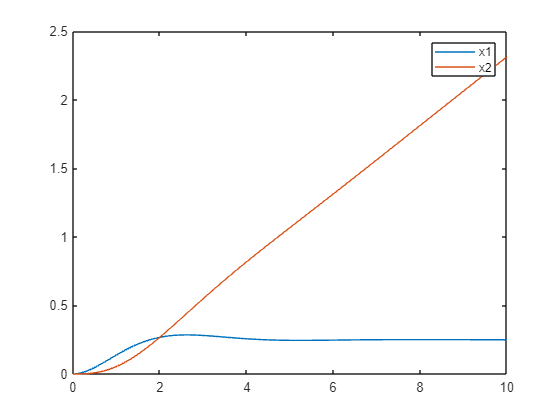

figure
plot(tOut,x)
legend('x1', 'x2')

### استخراج ویژگی های پاسخ سیستم

این دستور بر خلاف دیگر دستورات این بخش، سیستم را به عنوان ورودی نمی گیرد، بلکه با داشتن بردار زمان و بردار پاسخ سیستم (که از دستور پاسخ پله، ضربه یا هر دستور دیگری بدست آمده است)، به محاسبه و برگرداندن ویژگی های آن می پردازد

[`S = lsiminfo(y,t)`](https://127.0.0.1:31515/static/help/control/ref/lsiminfo.html#d124e91482)

y: یک بردار شامل پاسخ خروجی سیستم 

t: بردار زمانی متناسب با منحنی سیگنال پاسخ

[`S = lsiminfo(y,t,yfinal)`](https://127.0.0.1:31515/static/help/control/ref/lsiminfo.html#d124e91518)

yfinal: اگر با یک عدد مقدار پاسخ نهایی را مشخص کنید، تابع ویژگی ها را (مثلا زمان نشست) با توجه به آن محاسبه میکند. اگر مشخص نشود، به صورت پیش فرض آخرین مقدار سیگنال برای این انتخاب خواهد شد

[`S = lsiminfo(y,t,yfinal,yinit)`](https://127.0.0.1:31515/static/help/control/ref/lsiminfo.html#d124e91577)

yinit: محاسبات این تابع با صفر در نظر شرایط اولیه انجام میشود. در صورتی که سیستم دارای شرایط اولیه است، آن را به تابع دهید تا اشتباهی رخ ندهد.

        منظور از مقدار اولیه، مقدار خروجی سیستم قبل از اعمال ورودی است و نه مقادیر اولیه که در اینجا تنها در خروجی بازتاب میشوند

زمان نشست به طور پیش فرض 2 درصد حالت نهایی است. اگر به دنبال تغییر این مقدار هستید، با کمک زوج آرگومان زیر این کار را انجام دهید. مثلا 2 درصد باید به صورت 0.02 نوشته شود

[`S = lsiminfo(``___``,'SettlingTimeThreshold',ST)`](https://127.0.0.1:31515/static/help/control/ref/lsiminfo.html#d124e91637)

#### مثال


$$G=\frac{-4s+4}{s^3 +1\ldotp 5s^2 +0\ldotp 8s+0\ldotp 3}$$


sys = tf(4 * [-1 1], [1 1.5 0.8 0.3]);
[y, t] = impulse(sys);
S = lsiminfo(y, t)

S = struct with fields:
    TransientTime: 19.9148
     SettlingTime: 24.2115
              Min: -0.9770
          MinTime: 0.5526
              Max: 3.9991
          MaxTime: 4.0525

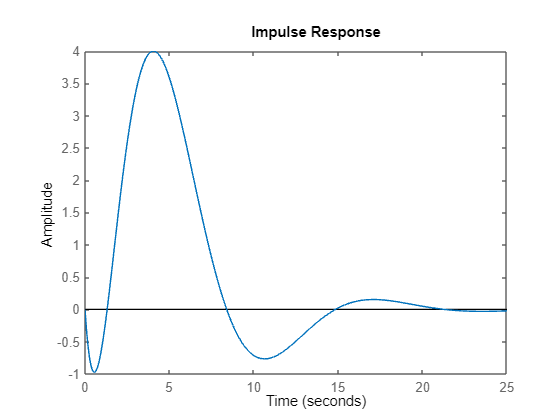

figure
impulse(sys)